clear; clc; close all;

% Audio Recording
fs = 44100; 
recordDuration = 5; 
recObj = audiorecorder(fs, 16, 1); 
disp('Recording...');

Recording...


recordblocking(recObj, recordDuration); 
disp('Recording done.');

Recording done.


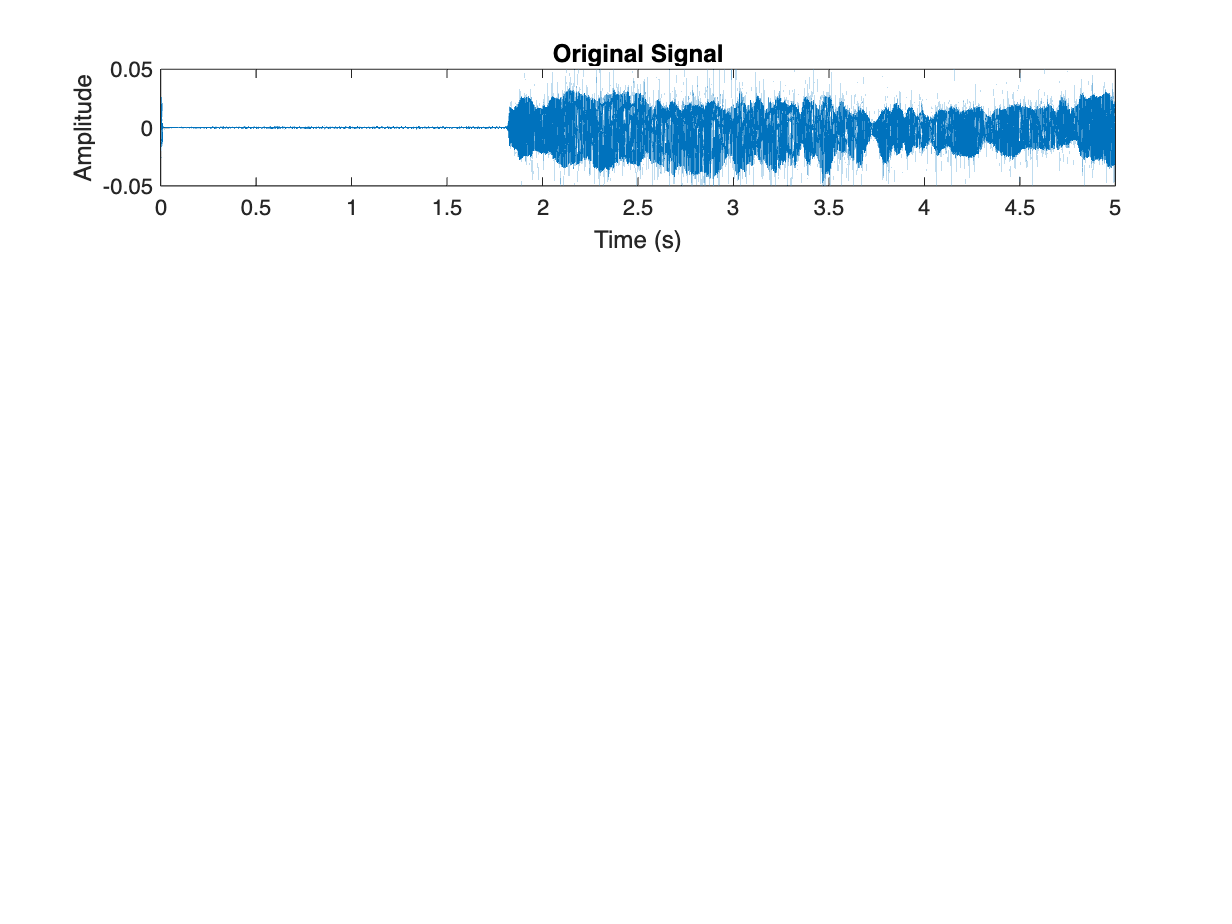


audioData = getaudiodata(recObj); 

% Original signal
figure;
subplot(4, 1, 1);
plot((1:length(audioData)) / fs, audioData); 
title('Original Signal');
xlabel('Time (s)');
ylabel('Amplitude');

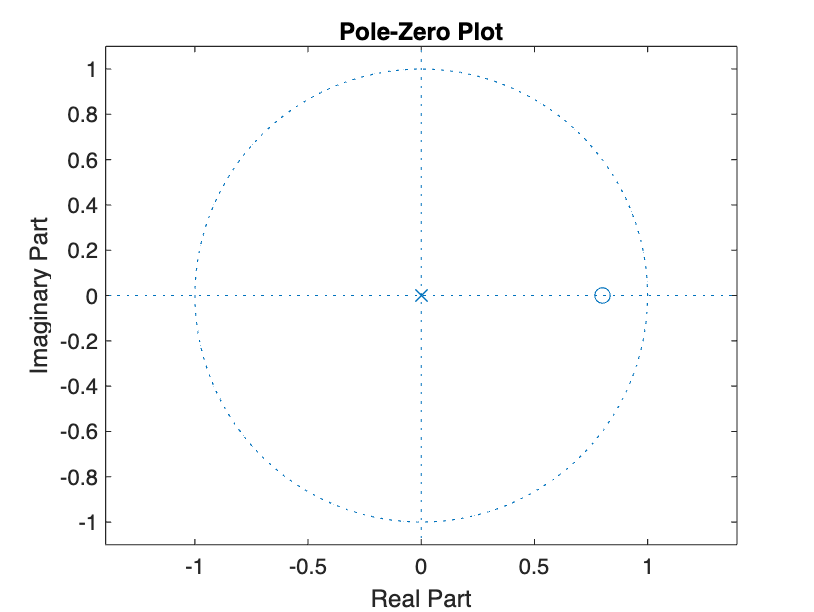


% Simple Pole-Zero Filter
b = [1 -0.8]; 
a = [1]; 
filteredData = filter(b, a, audioData);

% Pole-zero visualization
figure;
zplane(b, a);
title('Pole-Zero Plot');

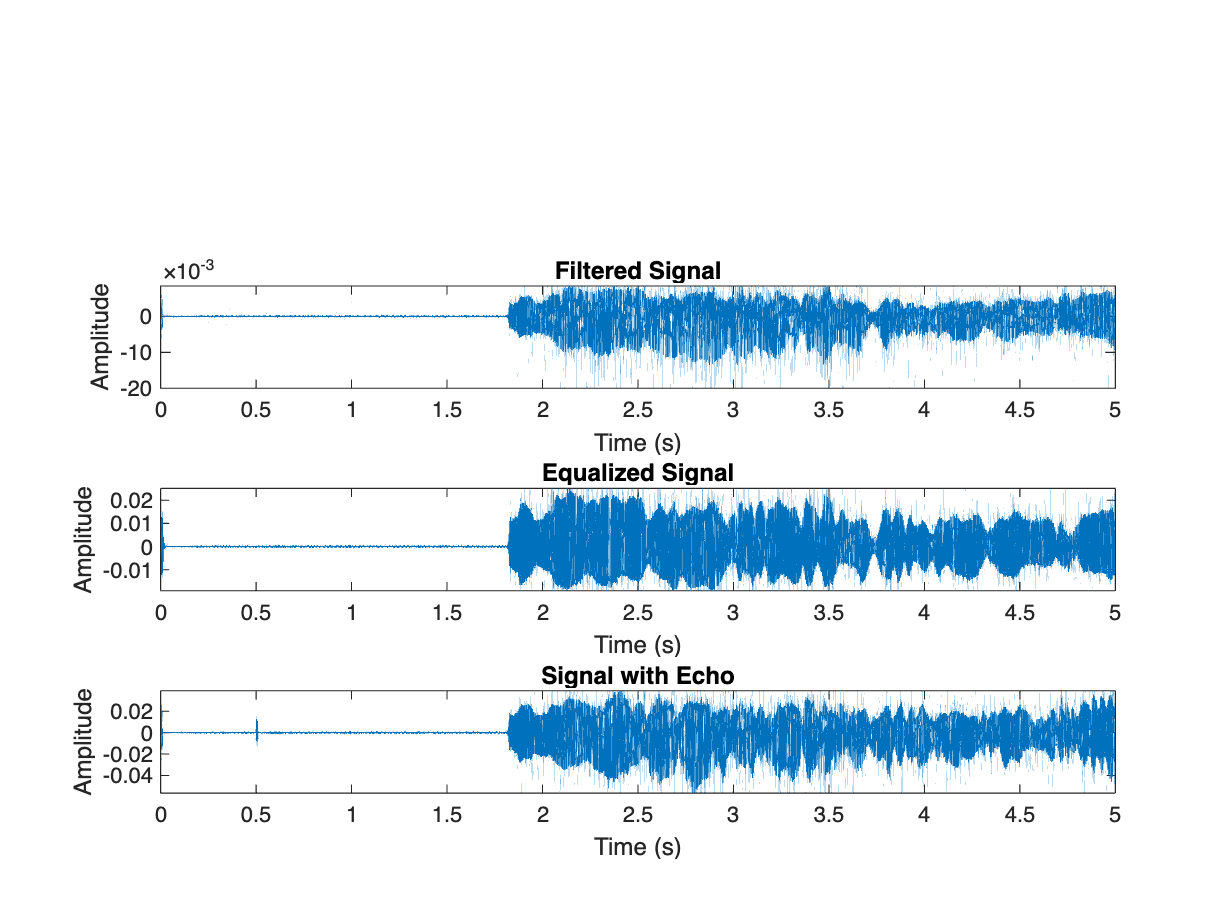


% Plotting the filtered signal
subplot(4, 1, 2);
plot((1:length(filteredData)) / fs, filteredData); 
title('Filtered Signal');
xlabel('Time (s)');
ylabel('Amplitude');

% Equalizer Design
freqBands = [50, 100, 200, 400, 800, 1600, 3200, 6400, 12800, 20000];
gains = [1, 0.8, 1.2, 1, 1.5, 1, 0.9, 1.1, 0.7];
eqData = zeros(size(audioData));

for i = 1:length(freqBands) - 1
    if freqBands(i) < fs / 2 && freqBands(i + 1) < fs / 2
        bandFilt = designfilt('bandpassiir', ...
            'FilterOrder', 4, ...
            'HalfPowerFrequency1', freqBands(i), ...
            'HalfPowerFrequency2', freqBands(i + 1), ...
            'SampleRate', fs);
        bandPassData = filter(bandFilt, audioData);
        eqData = eqData + gains(i) * bandPassData;
    end
end

subplot(4, 1, 3);
plot((1:length(eqData)) / fs, eqData); 
title('Equalized Signal');
xlabel('Time (s)');
ylabel('Amplitude');

% Adding Echo Effect
delayTime = 0.5; 
delaySamples = round(delayTime * fs); 
delayed = [zeros(delaySamples, 1); audioData];
echoSignal = audioData + 0.5 * delayed(1:length(audioData));

subplot(4, 1, 4);
plot((1:length(echoSignal)) / fs, echoSignal); 
title('Signal with Echo');
xlabel('Time (s)');
ylabel('Amplitude');


% Playback
disp('Playing back the signals...');

Playing back the signals...


sound(filteredData, fs); pause(recordDuration + 1);
sound(eqData, fs); pause(recordDuration + 1);
sound(echoSignal, fs); pause(recordDuration + 1);
